HW4 Question 1

clear; clc;

f = @(x,y) 1./(3*(y.^2));
y_exact = @(x) x.^(1/3);          % Part a

h = -0.05;                          % backward step (1 -> 0) with |h|=0.05
x_grid = 1:-0.05:0;                 % 1.00, 0.95, ..., 0.00 (inclusive)
N = numel(x_grid);


part b

y_euler = nan(N,1);
y_euler(1) = 1.0;                   % y(1)=1
for i = 1:N-1
    yi = y_euler(i);
    % guard against division by zero / negative crossing near x=0
    if yi <= 0, yi = max(yi, 1e-12); end
    y_euler(i+1) = yi + h*f(x_grid(i), yi);
end


part c

y_rk4 = nan(N,1);
y_rk4(1) = 1.0;
for i = 1:N-1
    xi = x_grid(i); yi = y_rk4(i);
    yi = max(yi, 1e-12);
    k1 = f(xi, yi);
    k2 = f(xi + h/2, yi + (h/2)*k1);
    k3 = f(xi + h/2, yi + (h/2)*k2);
    k4 = f(xi + h,   yi + h*k3);
    y_rk4(i+1) = yi + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
end


part d

x_ab4 = 1.15:-0.05:0;                     % starts at 1.15 to use seeds then march to 0
M = numel(x_ab4);
y_ab4 = nan(M,1);

% Given seeds (align to first four entries: 1.15, 1.10, 1.05, 1.00)
seed_x = [1.15 1.10 1.05 1.00];
seed_y = [1.04768955317165, 1.03228011545637, 1.01639635681485, 1.00000000000000];
y_ab4(1:4) = seed_y(:);

% AB4 recurrence: y_{n+1} = y_n + h/24 * (55 f_n - 59 f_{n-1} + 37 f_{n-2} - 9 f_{n-3})
for n = 4:M-1
    fn   = f(x_ab4(n),   max(y_ab4(n),   1e-12));
    fn_1 = f(x_ab4(n-1), max(y_ab4(n-1), 1e-12));
    fn_2 = f(x_ab4(n-2), max(y_ab4(n-2), 1e-12));
    fn_3 = f(x_ab4(n-3), max(y_ab4(n-3), 1e-12));
    y_ab4(n+1) = y_ab4(n) + (h/24)*(55*fn - 59*fn_1 + 37*fn_2 - 9*fn_3);
end

% Extract AB4 values on the same x_grid (1.00, 0.95, ..., 0.00)
% Note: x_ab4 sequence includes 1.15 seed and then 1.10, 1.05, 1.00, 0.95, ..., 0.00
[~, ia, ib] = intersect(round(x_ab4,10), round(x_grid,10), 'stable');
y_ab4_on_grid = nan(N,1);
y_ab4_on_grid(ib) = y_ab4(ia);

%------------------------------
% Exact values and errors
%------------------------------
y_true = y_exact(x_grid).';
err_euler = y_true - y_euler;
err_rk4   = y_true - y_rk4;
err_ab4   = y_true - y_ab4_on_grid;

%------------------------------
% Assemble table
%------------------------------
T = table( ...
    x_grid.', y_true, y_euler, err_euler, y_rk4, err_rk4, y_ab4_on_grid, err_ab4, ...
    'VariableNames', {'x','y_exact','y_euler','err_euler','y_rk4','err_rk4','y_ab4','err_ab4'} ...
);

disp('==== Q1: Exact vs Euler / RK4 / AB4 (h = 0.05 backward) ====');

==== Q1: Exact vs Euler / RK4 / AB4 (h = 0.05 backward) ====


disp(T);

     x      y_exact    y_euler     err_euler      y_rk4      err_rk4       y_ab4       err_ab4  
    ____    _______    _______    ___________    _______    __________    _______    ___________

       1          1          1              0          1             0          1              0
    0.95    0.98305    0.98333    -0.00028576    0.98305    2.3155e-10    0.98305    -3.1327e-07
     0.9    0.96549     0.9661    -0.00060752    0.96549    5.3542e-10    0.96549    -7.3196e-07
    0.85    0.94727    0.94824    -0.00097172    0.94727    9.3811e-10    0.94727    -1.2672e-06
     0.8    0.92832     0.9297     -0.0013863    0.92832     1.478e-09    0.92832    -1.9754e-06
    0.75    0.90856    0.91042     -0.0018615   

Plot

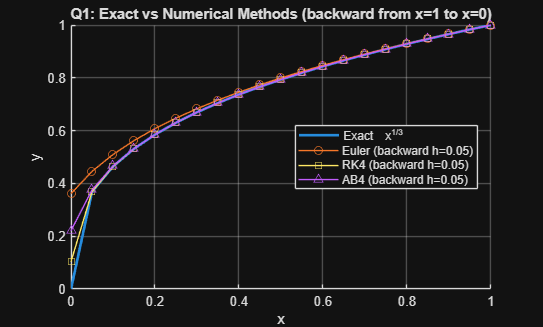

figure(1); clf; hold on; grid on;
plot(x_grid, y_true,  'LineWidth', 2, 'DisplayName','Exact  x^{1/3}');
plot(x_grid, y_euler, 'o-','DisplayName','Euler (backward h=0.05)');
plot(x_grid, y_rk4,   's-','DisplayName','RK4 (backward h=0.05)');
plot(x_grid, y_ab4_on_grid, '^-','DisplayName','AB4 (backward h=0.05)');
xlabel('x'); ylabel('y');
title('Q1: Exact vs Numerical Methods (backward from x=1 to x=0)');
legend('Location','best');

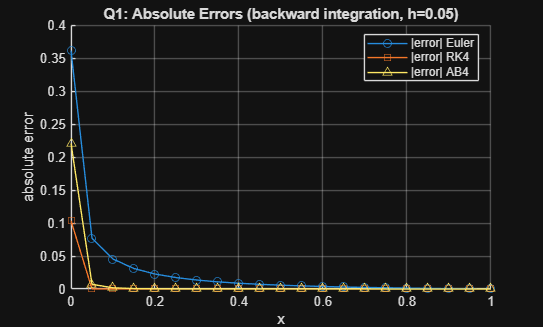


%------------------------------
% Plot absolute errors (semilogy to handle wide range)
%------------------------------
figure(2); clf; hold on; grid on;
semilogy(x_grid, abs(err_euler), 'o-','DisplayName','|error| Euler');
semilogy(x_grid, abs(err_rk4),   's-','DisplayName','|error| RK4');
semilogy(x_grid, abs(err_ab4),   '^-','DisplayName','|error| AB4');
xlabel('x'); ylabel('absolute error');
title('Q1: Absolute Errors (backward integration, h=0.05)');
legend('Location','best');


%------------------------------
% Brief accuracy summary in Command Window
%------------------------------
fprintf('\nMax |error| (Euler): %g\n', max(abs(err_euler),[],'omitnan'));


Max |error| (Euler): 0.361419


fprintf('Max |error| (RK4)  : %g\n', max(abs(err_rk4),[],'omitnan'));

Max |error| (RK4)  : 0.103455


fprintf('Max |error| (AB4)  : %g\n\n', max(abs(err_ab4),[],'omitnan'));

Max |error| (AB4)  : 0.220816

